# **Proof of Concept**

**Notes: **It needs Yalmip and OSQP. Yalmip should install himself automatically both on Windows and Linux. OSQP should automatically install on Linux, if there are any problems read the README. On Windows you need to install OSQP yourself.

There are TONs of other parameters and configuration you can tune and adapt, but atm you need to search them yourself.

clc;
clear variables;

## **Initialization**

%% INIT

% Instantiate main Class:
hpc = hpc_lab;

MAY be NOT Observable!
Size: 54800 bytes



% Core number
hpc.Nc = 9;

[TM] Remember to change Nh, Nv, epos, the parameter deviation vector, and the floorplan accordingly



% Rows and Columns
hpc.Nv = 3;

[TM] Remember to change Nh, epos, and the floorplan accordingly


hpc.Nh = 3;

[TM] Remember to change Nv, epos, and the floorplan accordingly



% Number of Voltage Domains
hpc.vd = 3;

% How the cores are distributed per domain
%hpc.VDom = ... ;
% Alternatively
hpc.default_VDom_config();

% Default Floorplan and Parameter deviation vector
hpc.default_floorplan_config();
hpc.create_model_deviation();

%Decide simulation frequency (discrete timing)
hpc.Ts = 5e-5;

%Decide total simulation time
hpc.tsim = 2;

%Presence/Absence of sensor noise:
hpc.sensor_noise = 1;

%Thermal model version
hpc.model_ver = 0;

#### After the configuration of the Thermal Model, run the model creation & others

hpc.model_init();

MAY be NOT Observable!


hpc.create_core_pw_noise();

#### Choose targets

% Initial Temperature condition
hpc.t_init = hpc.temp_amb*ones(hpc.Ns,1);

%Input maximum frequency
hpc.Ts_target;

tt = min(ceil(hpc.tsim / hpc.Ts_target)+1, (hpc.tsim/1e-4+1));

% Target Frequency Trajectory
hpc.frtrc = 3.45 * ones(tt, hpc.Nc);

%Target Power Budget
hpc.tot_pw_budget = 450/36*hpc.Nc*ones(tt,1);
tu = ceil(tt/4);
hpc.tot_pw_budget(tu+1:2*tu) = 2*hpc.Nc;
hpc.tot_pw_budget(2*tu+1:3*tu) = 5*hpc.Nc;
hpc.tot_pw_budget(3*tu+1:3*tu+ceil(tu/2)) = 3*hpc.Nc;
hpc.tot_pw_budget(3*tu+ceil(tu/2)+1:end) = 8*hpc.Nc;
hpc.quad_pw_budget = 450/36*hpc.Nc*ones(2,hpc.vd);

%Others, TODO
hpc.min_pw_red = 0.6;

#### After all the configurations are done, running the checks:

hpc.anteSimCheckTM();
hpc.anteSimCheckLab();
hpc.anteSimCheckPM();

## Run Autonomous thermal simulation

% Total time of simulation (s)
tsim_aut = 10;

% Changing Ts to improve the speed of simulation
hpc.Ts = 250e-6;
hpc.model_init();

MAY be NOT Observable!


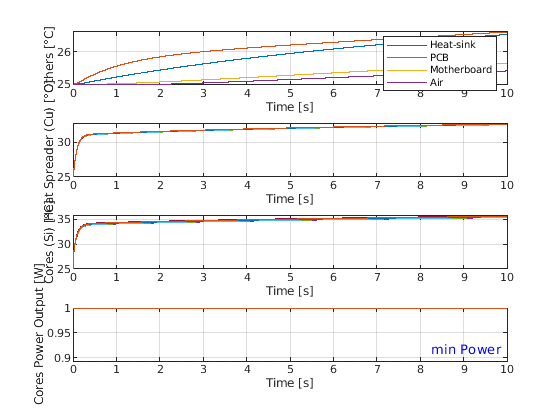

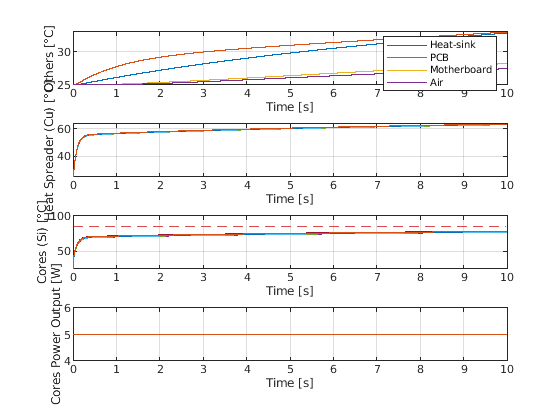

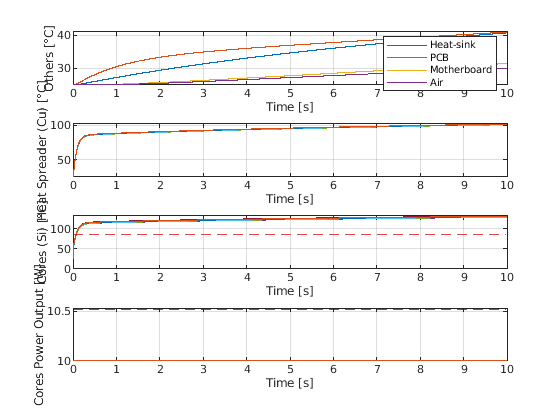

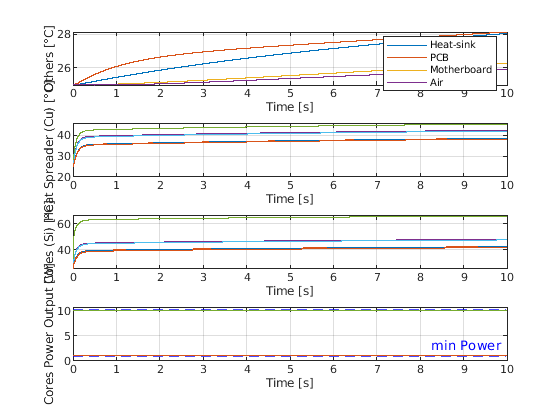

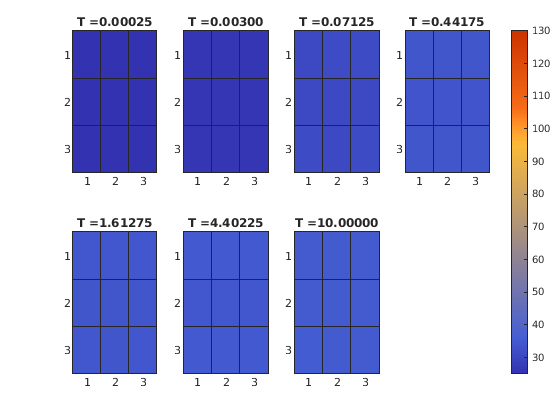

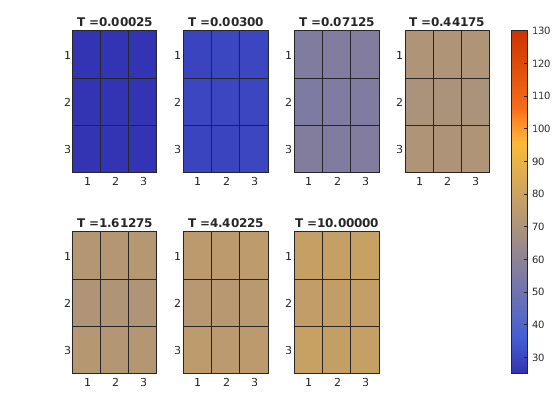

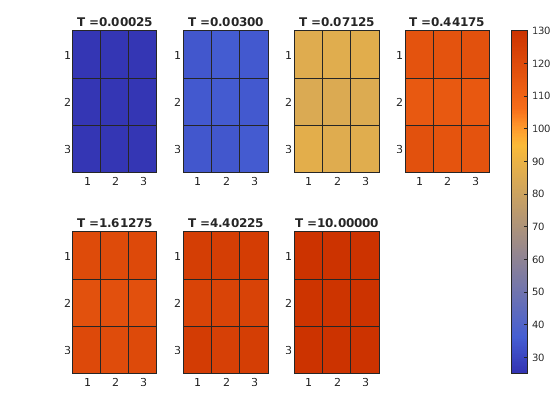

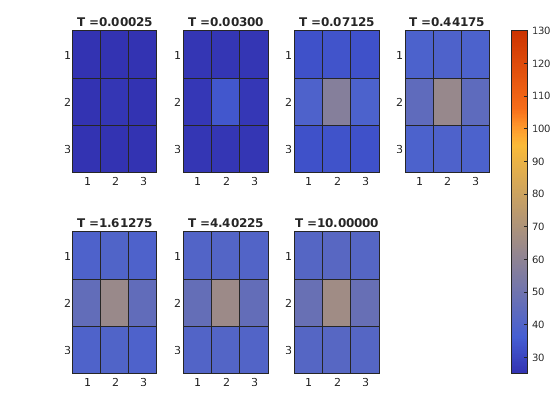

hpc.sim_tm_autonomous(tsim_aut)

hpc.Ts = 5e-5;
hpc.model_init();

MAY be NOT Observable!


### **Generate Workload trace:**

%Probability of each workload type [idle, int, float, mem, vec]
hpc.wl_prob = [0.0345 0.3448 0.3448 0.2414 0.0345];

%Minimum execution time (us) of each workload type
hpc.wl_min_exec_us = [510 100 100 480 520];	

%Mean execution time (us) of each workload type
hpc.wl_mean_exec_us = [520e2 210e1 180e1 560e2 1.2e6/1e1];

%Generate it
hpc.wltrc = hpc.generate_wl_trace(hpc.Nc, hpc.tsim, 0);


## **Controllers**

addpath('Controllers/');

## **Fuzzy Controller**

ctrl = Fuzzy;
ctrl.C = hpc.C;

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-4;


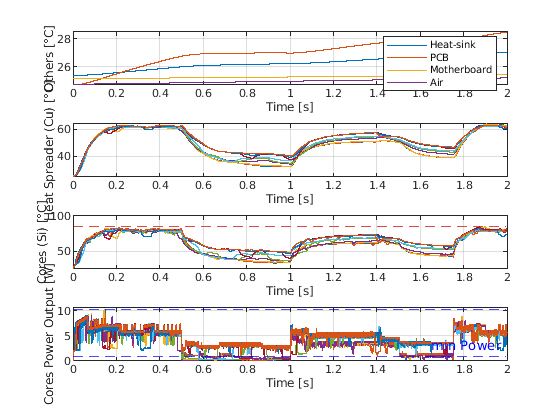

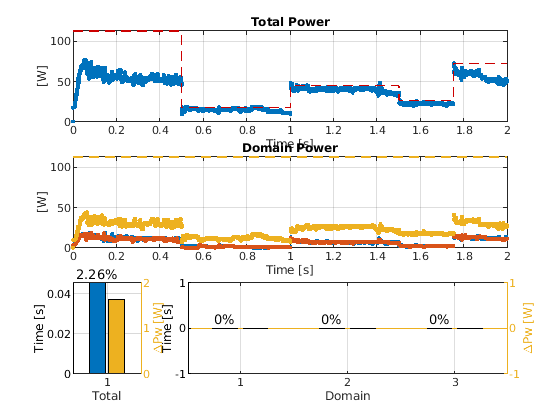

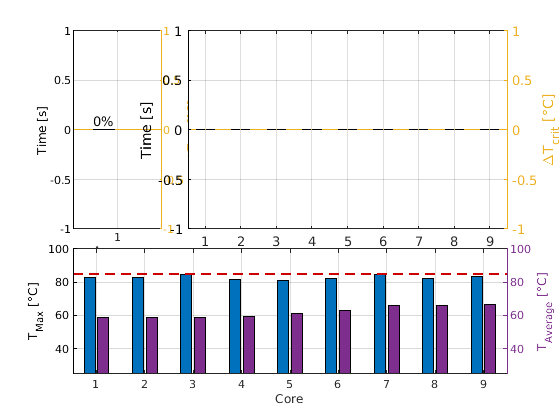

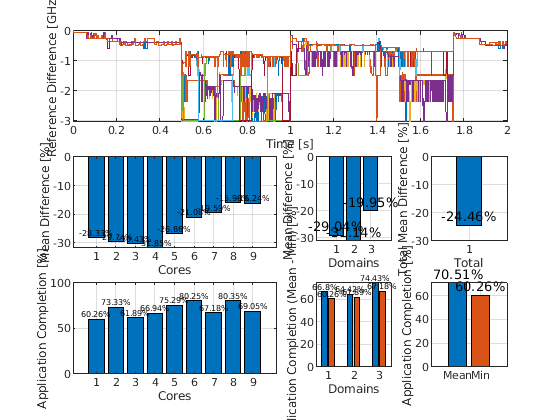

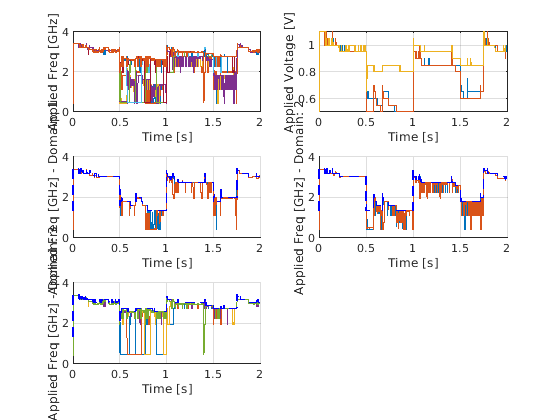

%Launch Simulation
tic;
hpc.simulation(ctrl,1);

toc;

Elapsed time is 26.728509 seconds.


## **SotA / CP MPC**

ctrl = cp_mpc;
ctrl.C = eye(hpc.Ns);

ctrl.save_solver_stats = 1;

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
ctrl.R2 = zeros(hpc.Nc);
ctrl.Q = zeros(hpc.Ns);

Optimizer object with 44 inputs (4 blocks) and 31 outputs (2 blocks). Solver: OSQP


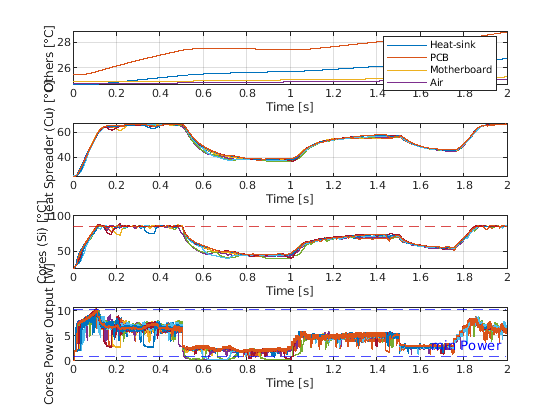

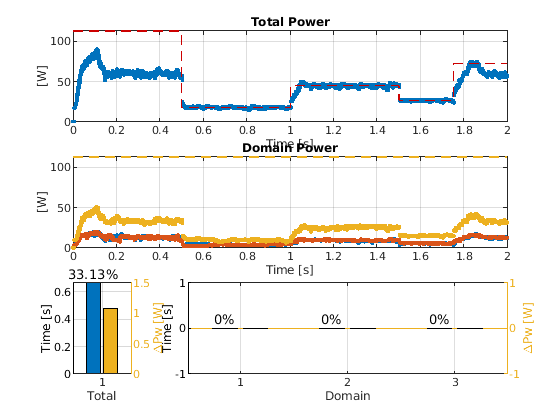

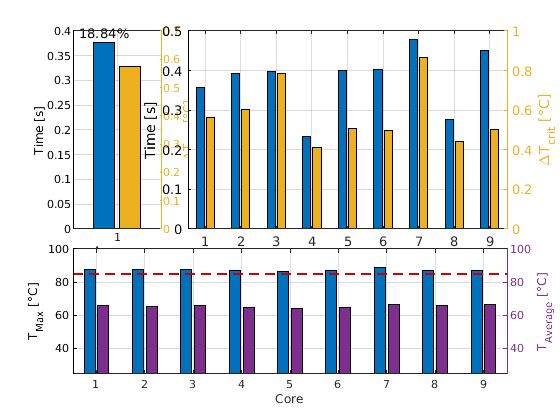

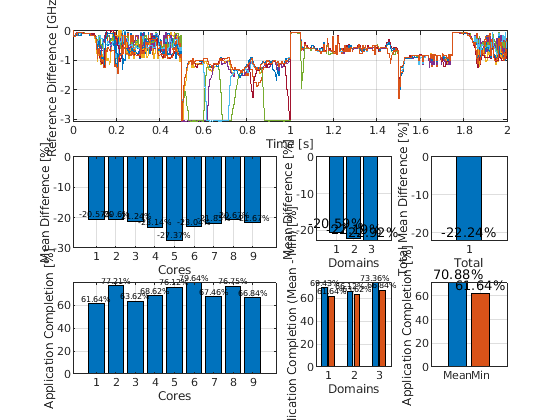

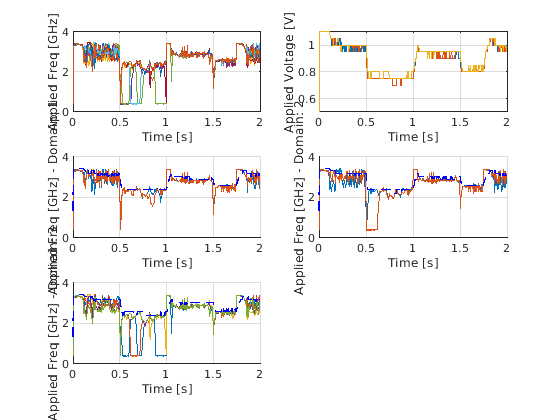

[CTRL][MPC] number of times the optimization algorithm failed:0/400


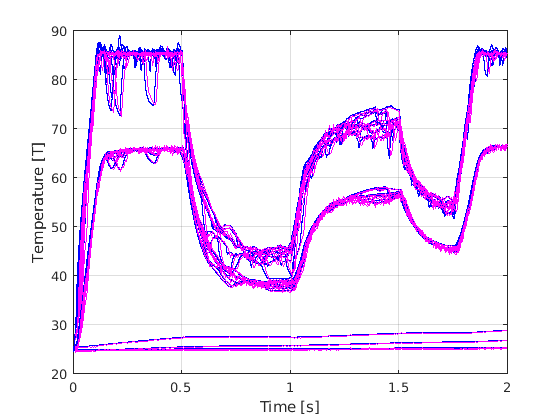

%Launch Simulation
tic;
[x, u, f, v, w] = hpc.simulation(ctrl,1);

res = hpc.stats_analysis(ctrl, x, u, f, v, w);
toc;

Elapsed time is 23.747994 seconds.


## **My-current-research MPC**

ctrl = black_wolf;
ctrl.C = eye(hpc.Ns);

%Controller frequency (s)
ctrl.Ts_ctrl = 5e-3;

%Robust Margins for T and P
ctrl.Cty = zeros(ctrl.Nhzn, hpc.Nc);
ctrl.Ctu = zeros(ctrl.Nhzn, hpc.Nc);

%Reference Tracking Objective Matrix
R_coeff = 10;
ctrl.R = R_coeff*eye(hpc.Nc);

%Others
R2_coeff = R_coeff/1;
ctrl.R2 = zeros(hpc.Nc);
for v=1:hpc.vd
	%Here I could create an accumulation thing that need to be
	%optimized (e.g. reduced) that contains the deltaF among quadrant 
	ctrl.R2 = ctrl.R2 + hpc.VDom(:,v)*hpc.VDom(:,v)' / sum(hpc.VDom(:,v))^2 * R2_coeff;
end
%TODO: Assuming that the diagonal is full
ctrl.R2(~eye(size(ctrl.R2))) = ctrl.R2(~eye(size(ctrl.R2))) * (-1);
cores_per_dom = sum(hpc.VDom);
ctrl.R2(logical(eye(size(ctrl.R2)))) = ctrl.R2(~~eye(size(ctrl.R2))) .* hpc.VDom*cores_per_dom'; %here I need ~~ to converto to logical values

ctrl.Q = zeros(hpc.Ns);

Optimizer object with 62 inputs (6 blocks) and 31 outputs (2 blocks). Solver: OSQP


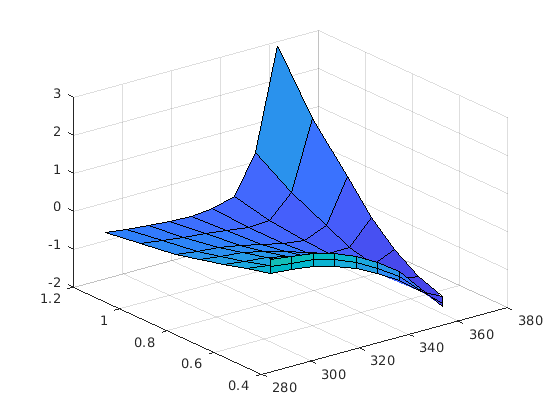

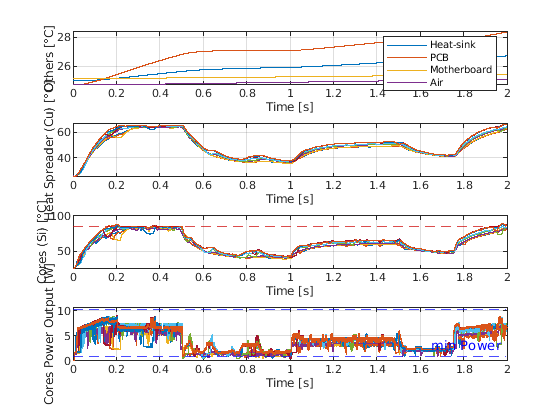

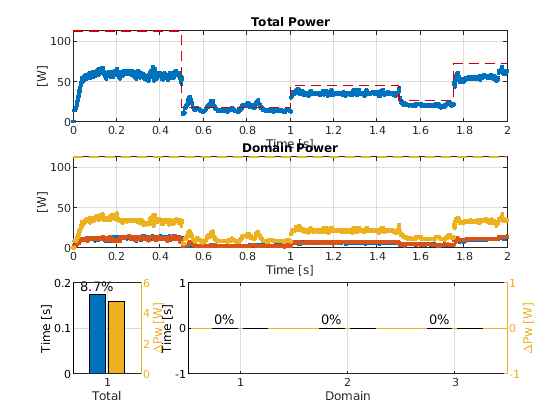

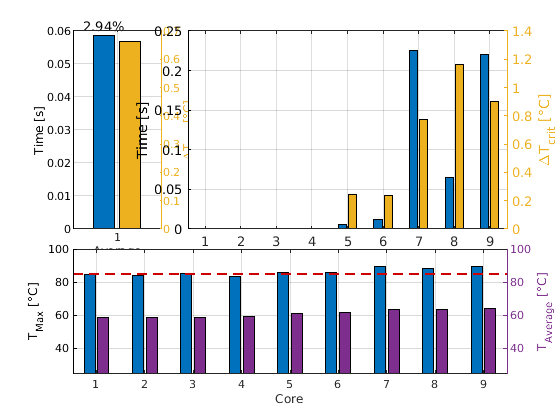

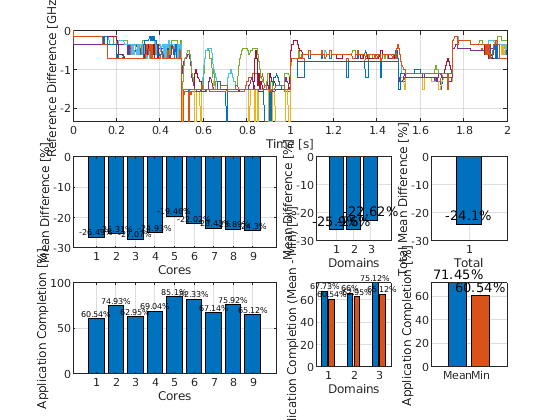

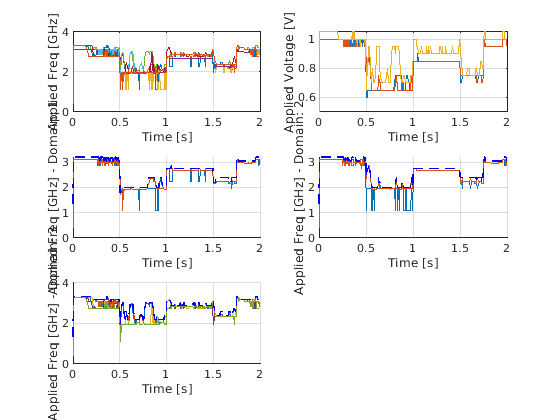

[CTRL][MPC] number of times the optimization algorithm failed:0/400


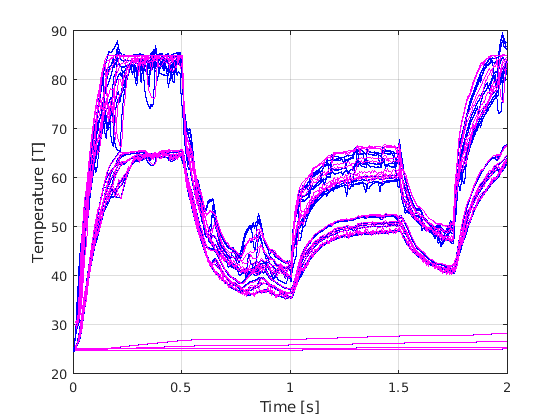

%Launch Simulation
tic;
[x, u, f, v, w] = hpc.simulation(ctrl,1);

toc;

Elapsed time is 18.559002 seconds.
